% Gabriel DiMartino

% Team F2
% Payton Peters
% Alex McCulloch
% Noah Sabra

clear;
clc;

## **Studio 3: Beam Design Modeling**

**Materials Information & Test Configuration**

Beam fabrication is being completed with square dowels of nearly equal width and height. Add code below to complete the following: Define the typical value for this dimension (**stickSize**) in inches. Define the test length (**testLength**) between the supports. 

stickSize = ((3/4) * (2/4)) + ((1/4)*(1/4));
testLength = 16;

fprintf("The area of the width height plane is %0.2f inches",stickSize)

The area of the width height plane is 0.44 inches

fprintf("The distance of the testing area is %0.2f inches",testLength)

The distance of the testing area is 16.00 inches

**Experimental Data Analysis**

Below, load the classroom data from Week 4 Studio to the array **testDataMOR**. Complete statistical calculations for the MOR data set; minimum, maximum, average and standard deviation. HINT: Visit Table 6.5.1 Statisical  and/or use Help search above.

% load data from MOR testing

testDataMor = readmatrix("MOR_experiment.xlsx");
 
% Find statistical values to support failure force prediction

minDataMor = min(testDataMor);
maxDataMor = max(testDataMor);
stdDataMor = std(testDataMor);

% Displacy values

fprintf("The minimum value is: %0.2f psi",minDataMor)

The minimum value is: 2630.00 psi

fprintf("The maximum value is %0.2f psi",maxDataMor)

The maximum value is 362553.00 psi

fprintf("The standard deviation value is %0.2f psi",stdDataMor)

The standard deviation value is 47602.80 psi

Below, create a bar graph, *bar (arrayName)*, displaying the variation among the samples. Label the graph axes, *xlabel("title")* and *ylabel("title")* with the descriptions Sample and Modulus of Rupture - psi, respectively. 

**Figure 1**

*Variations of MOR between samples*

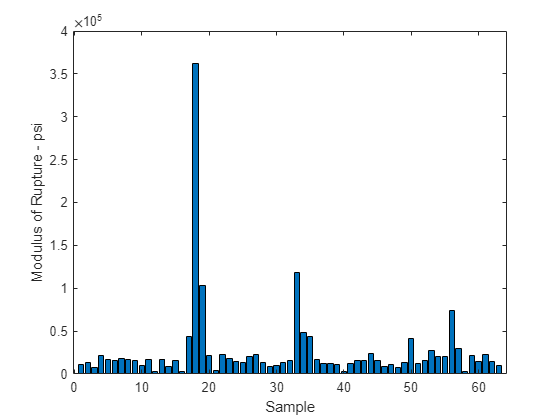

bar(testDataMor)
xlabel("Sample");
ylabel("Modulus of Rupture - psi");

**Beam Design Details** 

Below, define the geometry of the team's beam design. Include comments with a clear description of the beam cross-section. Establish an array (**stickC**) of the location of the center (vertically) of each of the sticks in the design from the base of the design. The units should be inches. Calculate the neutral axis, or vertical center, of the composite beam (**averageC**). Display the result in the command window. 

% The beam is using a T shapped design with a 3x2 base and 1 beam cutting
% through the center of the top
% 
cStick = [1/8,1/8,3/8,3/8,5/8,5/8,7/8];

averageC = mean(cStick);

fprintf("The neutral axis of the composite beam is %0.2f in",averageC)

The neutral axis of the composite beam is 0.45 in

**2nd Area Moment of Inertia (I)**

Below, calculate the array (**stickI**) of values for the individual contribution of each stick to the overall 2nd Area Moment of Interia.  Calculate the total 2nd Area Moment of Interia for the beam (**totalI**). Display the results in the command window.

% calculate 2nd Area Moment of Inertia

base = 1/4;
height = 1/4;

stickI = (((base*height)^3)/12) + (base*height).*(abs(cStick-averageC).^2);
% 
% Add calculations for stickI array and beam design totalI value
totalI = sum(stickI);

fprintf("The total inertia is %0.4f",totalI)

The total inertia is 0.0292

**Failure Force**

A traditional simply supported test has 3 points of contact; the two ends and the center where the force is applied. This test can be modifed to a 4-point test which separates the applied force to avoid damaging the sample during testing at the expected point of failure. Using the concepts from the reading calculate the expected failure forces for a 3-point test. Include force calculations that apply the average, maximum and minimum values of the Modulus of Rupture. (**aveFailForce3P**, **maxFailForce3P**, **minFailForce3P**). Clear identify each using comments.

% Calculate Failure Force for the statistical values calculated

aveFailForce3P = (mean(testDataMor)*(4*totalI))/(testLength*averageC);
maxFailForce3P = (maxDataMor*(4*totalI))/(testLength*averageC);
minFailForce3P = (minDataMor*(4*totalI))/(testLength*averageC);

% Output results
fprintf("The average fail force for this beam is %0.2f lbs",aveFailForce3P)

The average fail force for this beam is 423.41 lbs

fprintf("The maximum fail force for this beam is %0.2f lbs",maxFailForce3P)

The maximum fail force for this beam is 5920.40 lbs

fprintf("The minimum fail force for this beam is %0.2f lbs",minFailForce3P)

The minimum fail force for this beam is 42.95 lbs